# Derivative Rules for Combinations of Functions

As presented in [Derivative Rules for Powers](matlab:open('./derivativeRulesPowers.mlx')) and [Derivative Rules for Transcendental Functions](matlab:open('./derivativeRulesTranscendentals.mlx'))

**Power & Linearity Rules**                               **Transcendental Rules**            

$\frac{d}{dx}\left[x^n\right] = nx^{n-1}$   for constant $n$         $\frac{d}{dx}\left[\sin(x)\right] = \cos(x)$             $\frac{d}{dx}\left[e^x\right] = e^x$

$\frac{d}{dx}\left[cf(x)\right] = c\frac{df}{dx}$     for constant $c$         $\frac{d}{dx}\left[\cos(x)\right] = -\sin(x)$     $\frac{d}{dx}\left[\ln(x)\right] = \frac{1}{x}$      


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \frac{df}{dx}+\frac{dg}{dx}$$
                                                                                                              

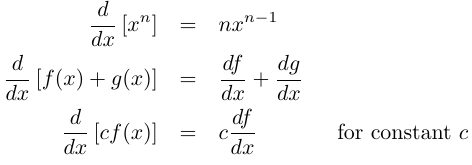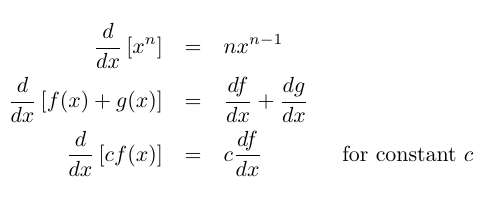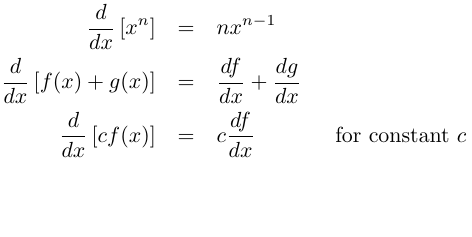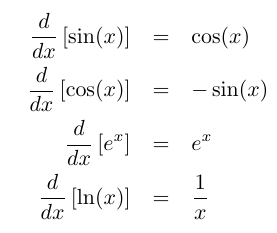With the exception of polynomials, however, most common functions are still missing from this list of rules. This script will present the two remaining fundamental rules for computing the derivatives of combinations of functions and present applications of these rules to a variety of mathematical and real-world situations.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB syntax. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Chain Rule

Consider two functions $y = f(x)$ and $z = g(x)$. After forming a new function $y_2 = f(z) = f(g(x))$ by composing $(f \circ g)(x)$, what is the derivative? 

### Derivation of the Chain Rule

The answer depends on being a bit more specific. What is the independent variable in the question about the derivative of a function created by composing two functions? If it is $z$ there is nothing new going on:


$$\frac{dy_2}{dz} = \frac{d}{dz}\left[f(z)\right] = \frac{df}{dz} = f'(z)$$


If it is $x$, though, then:


$$\frac{dy_2}{dx} = \frac{d}{dx}\left[(f\circ g)(x)\right] = \lim_{\Delta x \to 0} \frac{f(g(x+\Delta x))-f(g(x))}{\Delta x}$$
                                                            

                                   
$$=\lim_{\Delta x\to 0} \left(\frac{f((g(x+\Delta x)-g(x))+g(x))-f(g(x))}{g(x+\Delta x)-g(x)}\right)\left(\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$


Let $\Delta g = g(x+\Delta x) -g(x)$ denote the change in the $g$ value as a function of the change in the $x$ value $\Delta x$. Then:


$$\frac{dy_2}{dx} =\lim_{\Delta x \to 0}\left(\frac{f(g+\Delta g)-f(g)}{\Delta g}\right)\left(\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$
    

Note that $\lim_{\Delta x \to 0} \Delta g = \lim_{\Delta x \to 0} g(x+\Delta x)-g(x) = 0$, so:

   
$$\frac{dy_2}{dx} = \left(\lim_{\Delta g \to 0} \frac{f(g+\Delta g)-f(g)}{\Delta g}\right)\left(\lim_{\Delta x \to 0}\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$



$$=\frac{df}{dg}\cdot \frac{dg}{dx}$$
                                                             

                          
$$=f'(g)\cdot g'(x) = f'(g(x))\cdot g'(x)$$
                                                  

Visualize the chain rule by setting up functions `f(x)` and `g(x)` as well as choosing upper and lower bounds for the domain:

syms x                         % Create a symbolic variable x
figure 
f(x) =  x^3;   % User-defined function f(x), by default x^3
g(x) =  -.4*x+2;   % User-defined function g(x), by default -.4*x+2
a = -5;      % User-defined value of a, by default -5
b = 5;      % User-defined value of b, by default 5
if a < b                       % Check if a < b to ensure that instructions were followed
    bds = [a, b];
else                           % If ~(a<b), set the default bounds and warn the user
    bds = [-5, 5];
    disp("Your lower bound is not lower than your upper bound. Using default bounds of [-5, 5].")
end
                     % Run this section
% Set up and display the user-defined functions to the user
fx = f(x);                     % Set up the function to display its value
gx = g(x);                     % Set up the function to display its value
disp("The original functions are:")
displayFormula("f(x) = fx")
displayFormula("g(x) = gx")
% Then set up and display the combined function
disp("Combining the functions through composition:")
fg = f(g(x));                    % Set up the function to display its value
displayFormula("f(g(x)) = fg")   % Display the composed result
disp("Therefore,")
fg0 = f(g(bds(1)));              % Set up the function to display its value
g0 = g(bds(1));                  % Set up the function to display its value
a0 = bds(1);                     % Set up the point to display its value
displayFormula("g(a0) = g0")       % Display the result of evaluating g() at a point
disp("and")
displayFormula("f(g(a0)) = fg0") % Display the result of evaluating f(g()) at a point
%figure
showChainRule(@(x)f(x),@(x)g(x),bds,"f","g");

Then animate this plot by observing how the derivative of the combined function `f(g(x))` relates to the derivatives of each subcomponent `f(g)` and `g(x)`.

                  % Run this section
if ~exist("f","var") || ~exist("g","var") || ~exist("bds","var")
    % If the previous section hasn't run, set up the default values for the required variables
    syms x
    figure(1)
    f(x) = x^3;
    g(x) = -.4*x+2;
    bds = [-5 5];
end
[fh,gh,bds,gMin,gMax,cT,pf,pfT,pfg,pfgT,pg,pgT] = showChainRule(@(x)f(x),@(x)g(x),bds,"f","g");
animateChainRule(fh,gh,bds,gMin,gMax,cT,pf,pfT,pfg,pfgT,pg,pgT);
% animateChainRule is defined in Helper Functions
% animateChainRule loops over 100 values in bds to show how the derivative
% of the composite function is the product of the derivatives df/dg and
% dg/dx, such as when both left-hand tangents have negative slope but the
% right-hand tangent has a positive slope, etc.

### Application: Pendulum

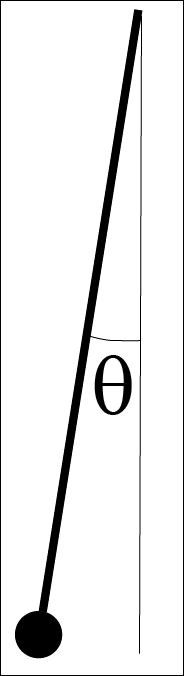

It can be shown that for small angles, the angle as a function of time for a pendulum is:


$$\theta(t) = \theta_0 \enspace \cos \left(t\sqrt{\frac{g}{L}} \right)$$


where $g$ is acceleration due to gravity, $L$ is the length of the pendulum, and $\theta_0$ is the initial angle of the pendulum. The angular velocity of the pendulum, $\omega(t)$, can be found by taking the derivative of $\theta(t)$ with respect to $t$. 

** Exercise 1**.

- Find the expression for angular velocity $\frac{d\theta}{dt} = \omega(t)$. 

-  Based on your knowledge of a pendulum, where would you expect the angular velocity to be zero? After thinking about this, use the expression you just found for $\omega(t)$and find a time (other than $t = 0$) where the pendulum is at rest. At this time, what is the value of $\theta(t)$? Is it where you would expect it to be?

- Similarly, the angular acceleration, $\alpha(t)$, of the pendulum can be found as the derivative of the angular velocity with respect to time. Find the expression for angular acceleration $\frac{d^2\theta}{dt^2}=\alpha(t)$. 

selectedPendulumAnswers= false;
showPendulumAnswers(selectedPendulumAnswers);

### Application: Related Rates

Consider a classic vinyl record that rotates at 45 rotations per minute on its record player.

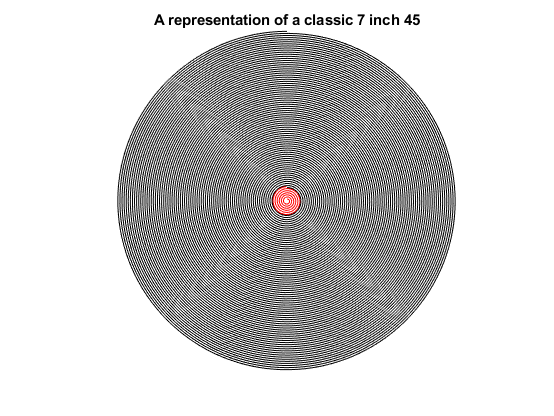

% This code draws a tight black spiral with a tight red spiral inside to
% produce the idea of a vinyl record
figure
recFig = drawRecord;      % drawRecord is in Helper Functions

This rotational speed means that $\frac{d\theta}{dt}$ is a constant. In fact, 45 rotations per minute means 

$\frac{d\theta}{dt}$ = $\left(45\frac{\text{rotations}}{\text{minute}}\right)\left(2\pi \text{ radians }\right)\left(\frac{1 \text{ minute}}{60 \text{ seconds}}\right)$ = $\frac{3\pi}{2}$ radians per second.

Place a needle near the outer edge of the record with $\theta = 0$ radians and follow its path along $r(\theta) = \left(7-\frac{7}{80}\theta\right)$ inches and observe it as it progresses towards the inner edge. This path is traced out by the yellow star in the plot below.

thetaN = linspace(0,23*pi,184);
if exist("recFig","var")                     % Check if the record figure has been generated locally
    hold on
    pN = plot(recFig.CurrentAxes,0,7,"y*");  % If so, plot a new point on top of the same figure of the record
    hold off
elseif ~exist("recFigWPt","var")             % Check if the record animation has been run locally
    figure
    recFigWPt = drawRecord;                  % If not, generate a local figure of the record
    hold on
    pN = plot(0,7,"y*");                     % Then add the point on top of the record figure
    hold off
end
for k = 1:184                                % Animate the position of the needle as the record plays
    pN.XData = (7-7/80*thetaN(k))*cos(thetaN(k));
    pN.YData = (7-7/80*thetaN(k))*sin(thetaN(k));
    drawnow
end
hold off
 

The needle, represented by the yellow star, moves towards the center of the record as time progresses. Use calculus to compute the rate at which $r$, the distance from the needle to the center, is changing after 45 seconds of playing time. 

** Exercise 2**.

- What is the angle, $\theta$, after 45 seconds of playing time? Please give your answer in radians.

theta = 0;         % User-input solution for theta(45 seconds) in radians

         2. What is the angular speed, $\frac{dr}{d\theta}$, after 45 seconds of playing time? Please give your answer in inches per radian.

angularSpeed = 0;  % User-input solution for dr/dtheta in inches/radian

         3. What is the linear speed, $\frac{dr}{dt}$, after 45 seconds of playing time? Please give your answer in inches per second.

linearSpeed = 0;   % User-input solution for dr/dt in inches/second
checkSpeed(theta,angularSpeed,linearSpeed);   % checkSpeed is defined in Helper Functions
% checkSpeed compares the input solutions of theta, angularSpeed, and
% linearSpeed to their correct values and displays feedback. When correct,
% the feedback includes the solution with appropriate units
                           % Run this section

### Practice Chain Rule Problems

Generate randomized practice problems. First, click **Initialize Values** once to get started. Then each time you want a new problem, click the **Generate Problem** button each time to create a new problem. After solving the problem, input your solution as MATLAB code and click the **Check Answer** button.  

  **Pro-tip**. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators. MATLAB syntax is `exp(7*t^(2/3))` for $e^{7t^{2/3}}$, `sin(7*cos(4*r-6))` for $\sin(7\cos(4r-6))$ and `log(z/2)` for $\ln\left(\frac{z}{2}\right)$.

clear                                % Clear variables
syms t r x z                         % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totCRProbs = 0;                      % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
                         % Run this section
disp("Values initialized for Chain Rule Practice.")

___________________________________________________________

Generate a chain rule problem:

% Check if the previous section has run
% If not, provide inging. If so, generate a problem.
if ~exist("totCRProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = genProbType(varOpts,3);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totCRProbs = totCRProbs+1;               % Increase the count of total problems attempted
end
                       % Run this section

myAnswer = r;     % User-defined solution, default value t
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totCRProbs,adjustCount,myFun,varChoice,myAnswer,3,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

                        % Run this section
analyzeResults(totCRProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults is defined in Helper Functions
% Compute the percentage of initially correct solutions out of the total
% problems attempted, subsequent attempts are not scored

#### Practice App

If you would prefer to practice in the Calculus Flashcards app, you can start it by clicking on the image below. You should set it for "Chain Rule" in the Derivatives section. The app will open in a new window.

[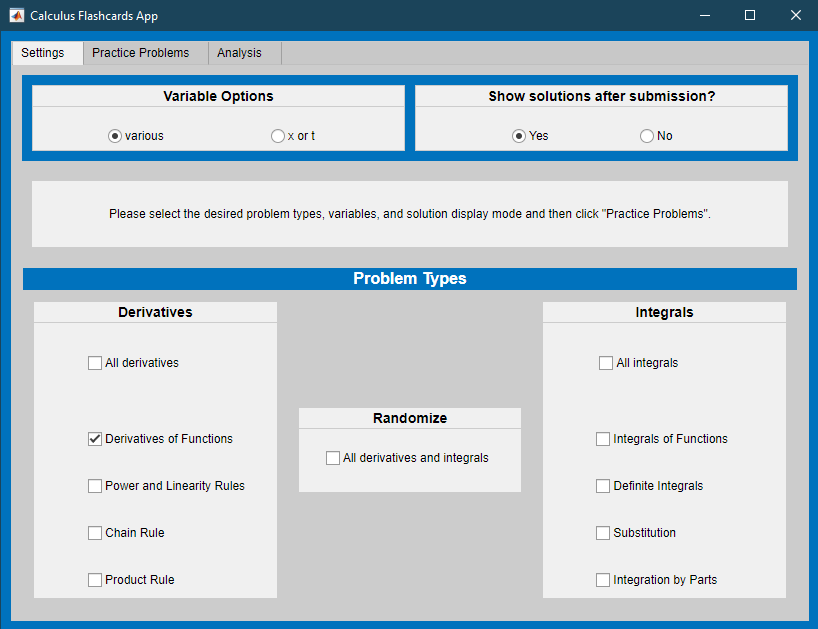](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

## Product Rule

syms x                                   % Create a symbolic variable
f = symfun(3*x+1,x);      % User-defined symbolic function, default is 3*x+1
g = symfun(2*x^2-x+2,x);      % User-defined symbolic function, default is 2*x^2-x+2
pt = 3;        % User-selected pt value, default is 3
h = 0.05;        % User-selected step size h, default is 0.05
                        % Run this section with options selected by the user

Select the desired features using the check boxes. `Show animation` cycles through all three individual labels and closes with all labels on. `Show axes` allows explicit investigations of the scale of each component by providing axis labels.

showAnimation = false; showAxes = true;

To focus on a particular component or two without the animation, select the corresponding check box. 

showFG = false ; showChange = false; showdfdg = false;
if ~exist("prAx","var")                    
    prAx = showProductRuleBasic(f,g,pt,h,["#4DBEEE" "#A2142F" "#77AC30"]);
end
% If no check boxes are selected, show a simple diagram of the product rule
if ~any([showAnimation showFG showChange showdfdg])
    showProductRule(prAx,f,g,pt,h,["#4DBEEE" "#A2142F" "#77AC30"],showAxes)
    % showProductRule is defined in Helper Functions
    % showProductRule takes two functions, a point, a step size, a set of
    %     colors, and a flag indicating whether to show the axes of the graph
    %     It generates an image consisting of four colored rectangles:
    %     The first is cols(1) and represents f*g
    %     The second and third are cols(3) and represent f*dg and g*df
    %     The fourth is cols(2) and represents dg*df
end
% If showAnimation is selected, animate the figure
if showAnimation
    if any([showFG showChange showdfdg])
        disp("When the animation is set to run, the individual selections are ignored by the script.")
        disp("To focus on individual selections, please unselect the 'Show animation' check box.")
    end
    animateProductRule(prAx,f,g,pt,h,["#4DBEEE" "#A2142F" "#77AC30"],showAxes) %#ok<*UNRCH>
    % animateProductRule is defined in Helper Functions
    % animateProductRule shows the basic product rule visualization and each
    % annotated component for a short time, then finishes with the fully
    % annotated plot
else
    % If any of the annotation boxes are selected, first generate the product
    % rule visualization, then annotate as requested
    if any([showFG showChange showdfdg])
        showProductRule(prAx,f,g,pt,h,["#4DBEEE" "#A2142F" "#77AC30"],showAxes)
        % showProductRule is defined in Helper Functions
        % showProductRule takes two functions, a point, a step size, a set of
        %     colors, and a flag indicating whether to show the axes of the graph
        %     It generates an image consisting of four colored rectangles:
        %     The first is cols(1) and represents f*g
        %     The second and third are cols(3) and represent f*dg and g*df
        %     The fourth is cols(2) and represents dg*df
    end
    % Annotate with Area = f(x)*g(x)
    if showFG && ~any([showChange showdfdg])
        annProdfg(f,g,pt,h,0)
    elseif showFG
        annProdfg(f,g,pt,h,1)
    end
    % Annotate with f(x)*dg + g(x)*df
    if showChange
        annProdChange(f,g,pt,h,"#77AC30")
    end
    % Annotate with df*dg
    if showdfdg
        annProddfdg(f,g,pt,h,"#A2142F")
    end
end



### Practice Product Rule Problems

Generate randomized practice problems. First, click **Initialize Values** once to get started. Then each time you want a new problem, click the **Generate Problem** button each time to create a new problem. After solving the problem, input your solution as MATLAB code and click the **Check Answer** button.  

  **Pro-tip**. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators. MATLAB syntax is `exp(7*t^(2/3))` for $e^{7t^{2/3}}$, `sin(7*cos(4*r-6))` for $\sin(7\cos(4r-6))$ and `log(z/2)` for $\ln\left(\frac{z}{2}\right)$.

clear                                % Clear variables
syms t r x z                         % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totPRProbs = 0;                      % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Product Rule Practice.")

___________________________________________________________

Generate a product rule problem:

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totPRProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = genProbType(varOpts,2);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totPRProbs = totPRProbs+1;               % Increase the count of total problems attempted
end
                          % Run this section

myAnswer = 10*5/2*z^(-7/2)*log(z)-10/z^(7/2);     % User-defined solution, default value r
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totPRProbs,adjustCount, ...
    myFun,varChoice,myAnswer,2,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

                     % Run this section
analyzeResults(totPRProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults is defined in Helper Functions
% Compute the percentage of initially correct solutions out of the total
% problems attempted, subsequent attempts are not scored

#### Practice App

If you would prefer to practice in the Calculus Flashcards app, you can start it by clicking on the image below. You should set it for "Product Rule" in the Derivatives section. The app will open in a new window.

[](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

### Application: Quotient Rule

One common combination of functions that deserves mention is $\frac{f(x)}{g(x)}$ for some functions $f(x)$ and $g(x)$ where $g(x)\neq 0$. Take the derivative:


$$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] =  \frac{d}{dx}\left[f(x)\cdot \left(\frac{1}{g(x)}\right)\right] = \frac{d}{dx}\left[f(x)\cdot \left(g(x)\right)^{-1}\right]$$
          

Applying the product rule, 

$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{d}{dx}\left[f(x)\right]\cdot \left(g(x)\right)^{-1}+f(x)\cdot\left(\frac{d}{dx}\left[\left(g(x)\right)^{-1}\right]\right)$.      

Applying the chain rule,


$$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{d}{dx}\left[f(x)\right]\cdot (g(x))^{-1} + f(x)\left(-(g(x))^{-2}\frac{d}{dx}\left[g(x)\right]\right)$$


and simplifying:

$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{f'(x)}{g(x)}-\frac{f(x)g'(x)}{(g(x))^2} = \frac{f'(x)g(x)-f(x)g'(x)}{(g(x))^2}$.         

### Practice Mixed Derivative Problems

Generate randomized practice problems. First, click **Initialize Values** once to get started. Then each time you want a new problem, click the **Generate Problem** button each time to create a new problem. After solving the problem, input your solution as MATLAB code and click the **Check Answer** button. 

  **Pro-tip**. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators. MATLAB syntax is `exp(7*t^(2/3))` for $e^{7t^{2/3}}$, `sin(7*cos(4*r-6))` for $\sin(7\cos(4r-6))$ and `log(z/2)` for $\ln\left(\frac{z}{2}\right)$.

clear                                % Clear variables
syms t r x z                         % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
maxProbIdx = 3;                      % Track the number of different types of problems offered
errorCount = zeros(maxProbIdx,1);    % Initialize a count of errors by problem type
totMDProbs = zeros(maxProbIdx,1);    % Initialize a count of total problems attempted by problem type
totAttempts = zeros(maxProbIdx,1);   % Initialize a count of total solutions offered by problem type
adjustCount = zeros(maxProbIdx,1);   % Preserve the counts if the user resubmits a solution
lastFive = zeros(maxProbIdx,5);      % Initialize a matrix to record the last five solution results
                         % Run this section
disp("Values initialized for Mixed Derivative Practice.")

___________________________________________________________

Generate a randomized derivative problem:

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totMDProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice,probType] = genProb(varOpts);  % genProb is defined in Helper Functions
    % genProb selects a problem type, sets up a variable and generates a randomized function
    totMDProbs(probType) = totMDProbs(probType)+1;  % Increase the count of total problems attempted
end
 

myAnswer = 2*cos(8*exp(2*t))*16*exp(2*t);      % User-defined solution, default value r
totAttempts(probType) = totAttempts(probType) + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totMDProbs,adjustCount, ...
    myFun,varChoice,myAnswer,probType,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                           % Run othns section

Once you have completed sufficient practice, track the overall results of your practice here:

                         % Run this section
giveFeedback(errorCount,totMDProbs,lastFive)

#### Practice App

If you would prefer to practice in the Calculus Flashcards app, you can start it by clicking on the image below. You should set it for "All Derivatives" in the Derivatives section. The app will open in a new window.

[](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

**Functions related to the Chain Rule**

Two main functions in this section lay out the basic chain rule visualization and animate the visualization by updating the relevant tangent lines.

function [fh,gh,bds,gMin,gMax,crTitle,pf,pfTitle,pfg,pfgTitle,pg,pgTitle] = showChainRule(fh,gh,bds,fstr,gstr)
syms x                      % Create a symbolic variable
% Compute the derivative of f and g as symbolic functions
df(x) = diff(fh(x),x);
dg(x) = diff(gh(x),x);
% Calculate the total length of the interval
bdsDiff = bds(2)-bds(1);
% Numerically determine the ranges for f and g over domain bds
% This allows aesthetically pleasing choices for the window sizes
xVals = bds(1):bdsDiff/1000:bds(2);
gVals = double(gh(xVals));
fVals = double(fh(gVals));
gMin = min(gVals);
gMax = max(gVals);
fMin = min(fVals);
fMax = max(fVals);
fdiff = .1*(fMax-fMin);
gdiff = .1*(gMax-gMin);

% Calculate the derivatives df/dg, dg/dx and df/dx at bds(1) as numbers
dfdg = double(df(gVals(1)));
dgdx = double(dg(xVals(1)));
dfdx = dfdg*dgdx;

% Create the basic figure with handles to the components that will be updated
% in the animation: crTitle, pf, pfTitle, pfg, pfgTitle, pg, and pgTitle
tLayout = tiledlayout(2,2);       % Set up a 2x2 tiled layout
crTitle = title(tLayout,"When $x_0$ = "+bds(1)+", then $\frac{df}{dg}\frac{dg}{dx} = ($" ...
    +dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx,"Interpreter","latex");
xlabel(tLayout,"$"+fstr+"("+gstr+"(x))$","Interpreter","latex")
nexttile(tLayout,1)              % This tile is in the top left corner
fplot(x,fh(x),[gMin gMax])
hold on
pf = plot([gMin,gMax],[dfdg*(gMin-gVals(1))+fVals(1),dfdg*(gMax-gVals(1))+fVals(1)]);
hold off
xlabel("$g$","Interpreter","latex")
ylabel("$f(g)$","Interpreter","latex")
pfTitle = title("$\frac{df}{dg} = $" + dfdg,"Interpreter","latex");
ylim([fMin-fdiff fMax+fdiff])    % Expand the window for better viewing
nexttile(tLayout,2,[2 1])        % This tile is the entire right half of the figure
fplot(x,fh(gh(x)),bds)
hold on
pfg = plot(bds,[fVals(1) dfdg*dg(bds(1))*bdsDiff+fVals(1)]);
hold off
xlabel("$x$","Interpreter","latex")
ylabel("$f(g(x))$","Interpreter","latex")
pfgTitle = title("$\frac{df}{dx} = $"+dfdx,"Interpreter","latex");
ylim([fMin-fdiff fMax+fdiff])    % Expand the window for better viewing
nexttile(tLayout,3)              % This tile is in the bottom left corner
fplot(x,gh(x),bds)
hold on
pg = plot(bds,[gVals(1) dg(bds(1))*bdsDiff+gVals(1)]);
hold off
xlabel("$x$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
pgTitle = title("$\frac{dg}{dx} = $" + dgdx,"Interpreter","latex");
ylim([gMin-gdiff gMax+gdiff])    % Expand the window for better viewing
end

function animateChainRule(fh,gh,bds,gMin,gMax,crTitle,pf,pfTitle,pfg,pfgTitle,pg,pgTitle)
syms x                      % Create a symbolic variable
% Compute the derivative of f and g as symbolic functions
df(x) = diff(fh(x),x);
dg(x) = diff(gh(x),x);
% Loop over 100 steps covering the domain and plot the
for x0 = linspace(bds(1),bds(2),100)

    dgdx = double(dg(x0));
    fpt = double(fh(gh(x0)));
    gpt = double(gh(x0));
    dfdg = double(df(gpt));
    dfdx = dfdg*dgdx;
    crTitle.String = "When $x_0$ = "+x0+", then $\frac{df}{dg}\frac{dg}{dx} = ($" ...
        +dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx;
    pf.YData = [dfdg*(gMin-gpt)+fh(gpt) dfdg*(gMax-gpt)+fh(gpt)];
    pfTitle.String = "$\frac{df}{dg} = $" + dfdg;
    pfg.YData = [dfdx*(bds(1)-x0)+fpt dfdx*(bds(2)-x0)+fpt];
    pfgTitle.String = "$\frac{df}{dx} = $"+dfdx;
    pg.YData = [dgdx*(bds(1)-x0)+gpt dgdx*(bds(2)-x0)+gpt];
    pgTitle.String = "$\frac{dg}{dx} = $" + dgdx;
    drawnow
end
crTitle.String = "When $x_0$ = "+bds(2)+", then $\frac{df}{dg}\frac{dg}{dx} = ($" ...
    +dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx;
drawnow
end

**Show answers to Exercises**

function showPendulumAnswers(click)
% showPendulumAnswers displays the solutions and commentary to the pendulum
% exercise, including demonstrating the use of units with symbolic results
u = symunit;
if ~click
    clear tOmegaIsZero omega alpha theta_0 g L
else
    syms theta_0 t g L omega theta %#ok<NASGU> 
    assume(t > 0 & g/L > 0)
    thetaFunc = theta_0 * cos(t * sqrt(g/L));
    disp("The answer to Exercise 1.1 is:")
    disp(" ")
    omegaAns = diff(thetaFunc,t); 
    displayFormula("omega(t) = omegaAns")
    disp(" ")
    disp("The answer to Exercise 1.2 is: ")
    disp(" ")
    tOmegaIsZeroAns = u.sec * solve(omegaAns == 0,'ReturnConditions',false);
    pendulumStoppedAngleAns = subs(thetaFunc,t,separateUnits(tOmegaIsZeroAns)); %#ok<NASGU>
    displayFormula("t_0=tOmegaIsZeroAns")
    displayFormula("theta(t_0) = pendulumStoppedAngleAns")
    disp("The pendulum will stop at the same angle that it was released from, but on the other side!")
    disp("Any time the pendulum reaches this angle (the maximum angle), it should be at rest.")
    disp(" ")
    disp("The answer to Exercise 1.3 is: ")
    disp(" ")
    alphaAns = diff(omegaAns,t); %#ok<NASGU>
    displayFormula("alpha(t) = alphaAns")
end
end

function recFig = drawRecord
recFig = gcf;
theta = linspace(0,25*pi,10000);
plot(7/80*(theta(1:800)+1).*sin(6*theta(1:800)),7/80*(theta(1:800)+1).*cos(6*theta(1:800)),"r-")
hold on
plot(7/80*(theta+6.726).*sin(6*(theta)),7/80*(theta+6.726).*cos(6*(theta)),"k-")
hold off
axis equal off
title("A representation of a classic 7 inch 45")
end

function checkSpeed(thetaAns,drdtheta,drdt)
syms dr dt d theta %#ok<NASGU> 
u = symunit;
drVal = -21*pi*u.in;
dtVal = 160*u.s;
drdtVal = drVal/dtVal; %#ok<NASGU>
thetaVal = 45*45*2*pi/60;
thetaValU = thetaVal*u.rad; %#ok<NASGU>
dthetadtAnsU = 3*pi/2*u.rad/u.s; %#ok<NASGU>
drdthetaAns = -7/80;
drdthetaAnsU = -7/80*u.in/u.rad; %#ok<NASGU>
answer = -7/80*(1/2)*((thetaVal+6.726)^2)^(-1/2)*2*(thetaVal+6.726)*45*2*pi/60;
if abs(thetaAns-thetaVal) < 1e-14     % A small tolerance to account for computational differences
    disp("Exercise 2.1. Is correct.")
    displayFormula("theta = thetaValU")
else
    disp("Exercise 2.1. Is incorrect.")
end
disp(" ")                              % Include a blank line between solution 2.1 and 2.2
if abs(drdtheta-drdthetaAns) < 1e-14  % A small tolerance to account for computational differences
    disp("Exercise 2.2. Is correct.")
    displayFormula("dr/(d*theta) = drdthetaAnsU")
elseif abs(drdtheta+drdthetaAns) < 1e-14
    disp("Exercise 2.2. Is incorrect. If r is getting larger, the derivative should be positive,")
    disp("and if r is getting smaller the derivative should be negative.")
else
    disp("Exercise 2.2. Is incorrect.")
    disp("Try simplifying before you compute the derivative.")
    disp("Remember that your answer should be exact.")
end
disp(" ")                              % Include a blank line between solution 2.2 and 2.3
if abs(drdt-answer) < 1e-14           % A small tolerance to account for computational differences
    disp("Exercise 2.3. Is correct.")
    displayFormula("dr/dt = (dr/(d*theta))*(d*theta/dt)")
    displayFormula("d*theta/dt = dthetadtAnsU")
    displayFormula("dr/dt = drdtVal")
elseif abs(drdt+answer) < 1e-14
    disp("Exercise 2.3. Is incorrect. If r is getting larger, the derivative should be positive,")
    disp("and if r is getting smaller the derivative should be negative.")
else
    disp("Exercise 2.3. Is incorrect. Remember to apply the chain rule:")
    displayFormula("dr/dt = (dr/(d*theta))*(d*theta/dt)")
end
end

**Functions related to the Product Rule **

To properly interact with different parts of the window and different orientations of the rectangles representing the product rule, this section includes many small helper functions as well as the primary functions that are called from the main script.

function [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h)
% calcPointVals takes two functions, f and g, a point pt and a step size h and returns
% each function evaluated at both pt and pt+h as numerical values
%
% Inputs:
% f and g are function handles, pt is a point, h is a step size
% Outputs:
% fx = f(pt), fxph = f(pt+h), gx = g(pt), gxph = g(pt+h) all as numbers
fx = double(f(pt));
fxph = double(f(pt+h));
gx = double(g(pt));
gxph = double(g(pt+h));
end

function [zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax)
% calcScaledPointVals takes the values f(x), f(x+h), g(x), g(x+h) and an
% axis handle ax and returns scaled values required to draw the rectangles
%
% Inputs:
%    fx = f(pt), fxph = f(pt+h), gx = g(pt), gxph = g(pt+h) as numbers
%    ax is an axis handle
% Outputs:
%    (zxs,zys) are the scaled coordinates of the origin (0,0)
%    fxs,fxphs,gxs,gxphs are the scaled coordinates of fx,fxph,gx,gxph,
%    respectively
xlimits = ax.XLim;                  % Identify the x limits of the axes ax
ylimits = ax.YLim;                  % Identify the y limits of the axes ax
xMin = xlimits(1);                  % The minimum x value, for readability
xMax = xlimits(2);                  % The maximum x value, for readibility
yMin = ylimits(1);                  % The minimum y value, for readibility
yMax = ylimits(2);                  % The maximum y value, for readibility
axInnerPosition = ax.InnerPosition; % Identify the area available for plotting inside the axes ax
yScale = axInnerPosition(4);        % Extract the height (length in the y-direction)
xScale = axInnerPosition(3);        % Extract the width (length in the x-direction)
x0 = axInnerPosition(1);            % Extract the x-coordinate of the lower-left corner
y0 = axInnerPosition(2);            % Extract the y-coordinate of the lower-left corner
% Calculate the scaled coordinates of the corners of the rectangle
zxs = (0-xMin)/(xMax-xMin)*xScale+x0;       % x=0
zys = (0-yMin)/(yMax-yMin)*yScale+y0;       % y=0
fxs = (fx-xMin)/(xMax-xMin)*xScale+x0;      % x=f(pt)
gxs = (gx-yMin)/(yMax-yMin)*yScale+y0;      % y=g(pt)
fxphs = (fxph-xMin)/(xMax-xMin)*xScale+x0;  % x=f(pt+h)
gxphs = (gxph-yMin)/(yMax-yMin)*yScale+y0;  % y=g(pt+h)
end

function prAxes = showProductRuleBasic(f,g,pt,h,cols) 
% showProductRule takes two functions, a point, a step size, and a set of colors
%     It generates an image consisting of four colored rectangles:
%     The first is cols(1) and represents f*g
%     The second and third are cols(3) and represent f*dg and g*df
%     The fourth is cols(2) and represents dg*df
% f and g are function handles
% pt is a point value
% h is a step size
% cols is a length 3 vector of colors
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);    % calcPointVals is defined in Helper Functions
s = scatter([0 fx fx 0], [0 0 gx gx],"white"); % plot the four corners of the rectangle to generate a plot
prAxes = s.Parent;
[xstart,ystart,dx,dy] = findCoords(0,0,fx,gx);  % findCoords is defined in Helper Functions
% Plot a rectangle representing f*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(1),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,0,fxph-fx,gx);       % findCoords is defined in Helper Functions
% Plot a rectangle representing df*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(0,gx,fx,gxph-gx);       % findCoords is defined in Helper Functions
% Plot a rectangle representing f*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,gx,fxph-fx,gxph-gx); % findCoords is defined in Helper Functions
% Plot a rectangle representing df*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(2),"EdgeColor","k")
% Add title and x- and y-labels to the plot
title("Product Rule")
xlabel("$f(x)$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
end

function showProductRule(prAxes,f,g,pt,h,cols,showAxes)
% showProductRule takes a figure handle, two functions, a point, a step size, a set of
%     colors, and a flag indicating whether to show the axes of the graph
%     It generates an image consisting of four colored rectangles:
%     The first is cols(1) and represents f*g
%     The second and third are cols(3) and represent f*dg and g*df
%     The fourth is cols(2) and represents dg*df
% prAx is an axis handle and f and g are function handles
% pt is a point value
% h is a step size
% cols is a length 3 vector of colors
% showAxes is a boolean
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);    % calcPointVals is defined in Helper Functions
scatter(prAxes,[0 fx fx 0], [0 0 gx gx],"white") % plot the four corners of the rectangle to generate a plot
[xstart,ystart,dx,dy] = findCoords(0,0,fx,gx);  % findCoords is defined in Helper Functions
% Plot a rectangle representing f*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(1),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,0,fxph-fx,gx);       % findCoords is defined in Helper Functions
% Plot a rectangle representing df*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(0,gx,fx,gxph-gx);       % findCoords is defined in Helper Functions
% Plot a rectangle representing f*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,gx,fxph-fx,gxph-gx); % findCoords is defined in Helper Functions
% Plot a rectangle representing df*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(2),"EdgeColor","k")
% Add title and x- and y-labels to the plot
title("Product Rule")
xlabel("$f(x)$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
% If not requested, hide the axes
if ~showAxes
    axis off
end
end

function mpt = findMidPt(opt1,opt2)
% findMidPt takes two points, opt1 and opt2, and returns their midpoint mpt
%     This function is defined for readability of the code
mpt = .5*(opt2+opt1);
end

function mpt = findMidCoord(opt1,opt2,shift)
% findMidCoord takes a pair of points, opt1 and opt2, and a shift and returns one point
if shift < 0
    % Return the largest value of the left/down-shifted midpoint or
    % most negative original point
    mpt = max([findMidPt(opt1,opt2)+shift min([opt1 opt2])]);
elseif shift == 0
    % Return a value that is centered between opt1 and opt2 if the distance
    % between them is at least .2. If the points are too close, shift
    % closer to the left/bottom to allow space for annotation, but do not
    % move further than the smaller of opt1 and opt2
    %    mpt = max([min([findMidPt(opt1,opt2) max([opt1 opt2])-.1]) 0]);
    mpt = max([min([findMidPt(opt1,opt2) max([opt1 opt2])-.1]) min([opt1,opt2])]);
else
    warning("This code was not designed for positive shifts.")
end
end

function [xpt,ypt] = findMidCoords(xopt1,xopt2,yopt1,yopt2,xshift,yshift)
% findMidCoords applies findMidCoord to both x- and y-coordinates at once
xpt = findMidCoord(xopt1,xopt2,xshift);
ypt = findMidCoord(yopt1,yopt2,yshift);
end

function [xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h)
% setMidPts takes the functions f and g, the point pt and step size h and
% returns a scaled coordinates for an approximate midpoint and origin
%
% Inputs:
% f and g are function handles, pt is a point, h is a step size
% Outputs:
% (xpt,ypt) are scaled coordinates between the origin and (f(pt),g(pt))
ax = gca;      % Define a handle to the current axis
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
% calcPointVals is defined in Helper Functions
% calcPointVals takes two functions, f and g, a point pt and a step size h and returns
% each function evaluated at both pt and pt+h as numerical values
[zxs,zys,fxs,~,gxs] = calcScaledPointVals(fx,fxph,gx,gxph,ax);
% calcScaledPointVals is defined in Helper Functions
% calcScaledPointVals takes the values f(x), f(x+h), g(x), g(x+h) and an
% axis handle ax and returns scaled values required to draw the rectangles
[xpt,ypt] = findMidCoords(zxs,fxs,zys,gxs,-.1,-.1);
% findMidCoords is defined in Helper Functions
% findMidCoords applies findMidCoord to both x- and y-coordinates at once
end

function [fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h)
% setBndryPts takes two functions f and g, a point pt and a step size h and
% returns the ordered values of f(pt), f(pt+h) and g(pt), g(pt+h) such that
% fLxs and gLxs are closer to while fFxs and gFxs are farther from the origin
ax = gca;
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
[zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax);
% Determine whether f(pt+h) or f(pt) is closer to 0
if abs(fxphs-zxs)>abs(fxs-zxs)
    fLxs = fxs;
    fFxs = fxphs;
else
    fLxs = fxphs;
    fFxs = fxs;
end
% Determine whether g(pt+h) or g(pt) is closer to 0
if abs(gxphs-zys)>abs(gxs-zys)
    gLxs = gxs;
    gFxs = gxphs;
else
    gLxs = gxphs;
    gFxs = gxs;
end
end

function annProdfg(f,g,pt,h,choice)
% annProdfg annotates the rectangle representing f*g
[xpt,ypt,zxs] = setMidPts(f,g,pt,h);
if choice
    % When multiple annotations are present, don't center the annotation
    [~,fLxs,xNpt,yNpt] = offsetPtCoordinates(f,g,pt,h);
    if fLxs>xNpt     % Shift away from the df*g annotation
        xReal = findMidPt(zxs,xNpt);
    else             % Shift less away from the df*g annotation
        xReal = findMidPt(xNpt,xpt);
    end
    % Adjust to y = yNpt-.025 to line up with the df*g annotation
    % Note that the height of the textbox is .05 scaled units
    % The width of the textbox is .216 scaled units
    % There are no checks here to prevent horizontal overlap so far
    dim = [xReal yNpt-.025 .216 .05];
else

    % setMidPts is defined in Helper Functions
    % setMidPts takes the functions f and g, the point pt and step size h and
    % returns a scaled coordinates for an approximate midpoint and origin
    dim = [xpt ypt .216 .05];
end
annotation("textbox",dim,"String","Area = $f(x)\cdot g(x)$","Interpreter","latex")
end

function annProddfdg(f,g,pt,h,col2)
% annProddfdg annotates the rectangle representing df*dg
[xpt,ypt] = setMidPts(f,g,pt,h);
% setMidPts is defined in Helper Functions
% setMidPts takes the functions f and g, the point pt and step size h and
% returns a scaled coordinates for an approximate midpoint and origin
[fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
% setBndryPts is defined in Helper Functions
% setBndryPts takes two functions f and g, a point pt and a step size h and
% returns the ordered values of f(pt), f(pt+h) and g(pt), g(pt+h) such that
% fLxs and gLxs are closer to while fFxs and gFxs are farther from the origin
[xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
% findMidCoods and findMidCoord are defined in Helper functions
% findMidCoords applies findMidCoord to both x- and y-coordinates at once
annotation("textarrow",[xUpt fLxs],[yUpt gLxs],"String","$\Delta f \cdot \Delta g$","TextEdgeColor",col2,"Color",col2,"Interpreter","latex")
end

function annProdChange(f,g,pt,h,col3)
% annProdChange annotates the pair of rectangles representing f*dg and g*df

% Determine coordinates using offsetPtCoordinates
[xUpt,fLxs,xNpt,yNpt,yUpt,gLxs] = offsetPtCoordinates(f,g,pt,h);
% Annotate the plot
annotation("textarrow",[xUpt fLxs],[yNpt yNpt],"String","$\Delta f \cdot g(x)$","TextEdgeColor",col3,"Interpreter","latex")
annotation("textarrow",[xNpt xNpt],[yUpt gLxs],"String","$f(x) \cdot \Delta g$","TextEdgeColor",col3,"Interpreter","latex")
end

function [xUpt,fLxs,xNpt,yNpt,yUpt,gLxs] = offsetPtCoordinates(f,g,pt,h)
% offsetPtCoordinates calculates reasonable positions for annotation

[xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h);
% setMidPts is defined in Helper Functions
% setMidPts takes the functions f and g, the point pt and step size h and
% returns a scaled coordinates for an approximate midpoint and origin

[fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
% setBndryPts is defined in Helper Functions
% setBndryPts takes two functions f and g, a point pt and a step size h and
% returns the ordered values of f(pt), f(pt+h) and g(pt), g(pt+h) such that
% fLxs and gLxs are closer to while fFxs and gFxs are farther from the origin

[xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
% findMidCoods and findMidCoord are defined in Helper functions
% findMidCoords applies findMidCoord to both x- and y-coordinates at once

% Calculate reasonable choices of coordinates to position the annotations
% vertically and horizontally
if fLxs > xpt && gLxs > ypt
    yNpt = ypt;
    xNpt = xpt;
elseif fLxs < xpt && gLxs > ypt
    yNpt = ypt;
    xNpt = findMidPt(xpt,zxs);
elseif fLxs > xpt && gLxs < ypt
    yNpt = findMidPt(ypt,zys);
    xNpt = xpt;
else
    yNpt = findMidPt(ypt,zys);
    xNpt = findMidPt(xpt,zxs);
end
end

function animateProductRule(prAxes,f,g,pt,h,cols,showAxes) %#ok<DEFNU> 
% animateProductRule shows the basic product rule visualization and each
% annotated component for a short time, then finishes with the fully
% annotated plot
showProductRule(prAxes,f,g,pt,h,cols,showAxes)  % showProductRule is defined in Helper Functions
% showProductRule takes a figure handle, two functions, a point, a step size, a set of
%     colors, and a flag indicating whether to show the axes of the graph
%     It generates an image consisting of four colored rectangles:
%     The first is cols(1) and represents f*g
%     The second and third are cols(3) and represent f*dg and g*df
%     The fourth is cols(2) and represents dg*df
pause(2)           % Pause for 2 seconds
col1 = cols(1);
col2 = cols(2);
col3 = cols(3);
showProductRule(prAxes,f,g,pt,h,[col1 "none" "none"],showAxes)
% showProductRule with only f*g colored
annProdfg(f,g,pt,h,0)      % Annotate f*g
pause(3)                   % Pause for 3 seconds
% showProductRule with only df*dg colored
showProductRule(prAxes,f,g,pt,h,["none" col2 "none"],showAxes)
annProddfdg(f,g,pt,h,col2) % Annotate df*dg
pause(3)                   % Pause for 3 seconds
% showProductRule with only f*dg and df*g colored
showProductRule(prAxes,f,g,pt,h,["none" "none" col3],showAxes)
annProdChange(f,g,pt,h,col3) % Annotate f*dg and g*df
pause(3)                   % Pause for 3 seconds
% showProductRule with everything colored and annotated
showProductRule(prAxes,f,g,pt,h,cols,showAxes)
annProdfg(f,g,pt,h,1)
annProddfdg(f,g,pt,h,col2)
annProdChange(f,g,pt,h,col3)
end

function [x0,y0,dx,dy] = findCoords(x0,y0,dx,dy)
% findCoords takes two points (x0,y0) and (x0+dx,y0+dy)
% and ensures that the output is the same two points with positive
% dx and dy such that x0<x0+dx and y0<y0+dy
if dx < 0
    x0 = double(x0+dx);
    dx = double(abs(dx));
end
if dy < 0
    y0 = double(y0+dy);
    dy = double(abs(dy));
end
end

**Functions related to Problem Generation and Analysis**

These functions generate randomized problems, account for different types of interactions with the user, and provide feedback and analysis to facilitate learning, including identifying which types of problems, if any, a user is struggling with.

function [myFun, varChoice, probType] = genProb(varOpts)
% genProb randomly selects a problem type and calls genProbType
%
% Inputs: varOpts is an array of possible variables
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked

% Determine a problem type randomly from the set [1,2,3]
% Type 1 is a simple derivative, Type 2 is a product rule and
% Type 3 is a chain rule
probType = randi([1 3],1);
[myFun,varChoice] = genProbType(varOpts,probType);
end

function [myFun, varChoice] = genProbType(varOpts, probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)], 1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
switch probType
    case 1 % Simple derivative
        myFun = genFunDiff(varChoice,[1,10],[]);  % Generate myFun
        % Display the derivative problem
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function ")
        displayFormula("f(varChoice) = myFun")
    case 2 % Product rule derivative
        syms f(x) g(x)
        [f(x),oldType] = genFunDiff(x,[1,7],[]);
        g(x) = genFunDiff(x,[1, 7],oldType);
        myFun = f(varChoice)*g(varChoice);        % Generate myFun
        % Display the derivative problem
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function ")
        displayFormula("f(varChoice)=myFun")
    case 3 % Chain rule derivative
        syms f(x) g(x)
        [f(x),oldType] = genFunDiff(x,[1,3],[]);
        g(x) = genFunDiff(x,[1,5],oldType);
        myFun = f(g(varChoice));                 % Generate myFun
        % Display the derivative problem
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function ")
        displayFormula("f(varChoice) = myFun")
end
end

function [myFun,type] = genFunDiff(var,bds,prevType)
% genFunDiff generates a random function with a simple derivative
%
% Inputs: var is the independent variable
%         bds is a 1x2 vector of increasing integer values that set
%             the range for the coefficients
%         prevType is an integer that identifies the type of function
%             created last
% Outputs: myFun is the generated symbolic function
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 bds(2)],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi([1 6],1);       % Randomly choose the function type

% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^(b);
    case 2
        f(t) = a*t^(b/c);
    case 3
        f(t) = a*exp(b*t);
        if prevType ~= 3
            disp("Remember that exp(x) is the notation for e^x in MATLAB.")
        end
    case 4
        f(t) = a*log(abs(b)*t);
        if prevType ~= 4
            disp("Remember that log(x) is the notation for a natural logarithm in MATLAB.")
        end
    case 5
        f(t) = a*sin(b*t+d);
    case 6
        f(t) = a*cos(b*t+d);
end

myFun = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts, ...
    totProbs,adjustCount,myFun,varChoice,myAnswer,probType,errorCount,lastFive)
if any(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
elseif any(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped(k):5),zeros(1,numSkipped(k))];
        else
            lastFive(k,:) = zeros(1,5);
        end
    end
    if sum(numSkipped) > 1
        disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
            "have been included in the count of errors.")
        disp(" ")
    elseif sum(numSkipped) == 1
        disp("The problem generated without an attempt at solution has been " + ...
            "included in the count of errors.")
        disp(" ")
    end
end

if length(totProbs)>1
    [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
else
    [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    % check1 generates correct answers by differentiating myFun with respect to varChoice and compares
    % the result to myAnswer before updating the integer errorCount and matrix lastFive
end
end

function [lastFive,errorCount] = check(myFunc,myVar,myAnswer,probType,errorCount,lastFive)
% check generates correct answers by differentiating or integrating
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         probType is an integer that tracks the question asked
%         errorCount is a matrix tracking errors by probType
%         lastFive is a matrix tracking success on the last five problems
%                  of each probType
% Output: updated lastFive and errorCount including analysis of myAnswer
[smLastFive,smErrorCount] = check1(myFunc,myVar,myAnswer,errorCount(probType,:),lastFive(probType,:)); 
% Restrict to a single known problem type and call check1
lastFive(probType,:) = smLastFive;       % Update the full matrix
errorCount(probType,:) = smErrorCount;   % Update the full matrix
end

function [lastFive,errorCount] = check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% check1 generates correct answers by differentiating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms df dt dr dz dx t r z x %#ok<NASGU> 
correctAnswer = diff(myFunc,myVar);
lastFive(1:4) = lastFive(2:5);
disp("When simplified, myAnswer is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif simplify(correctAnswer-myAnswer) == 0
    disp("That answer is correct. Another equivalent form is:")
    switch myVar
        case x
            displayFormula("df/dx = correctAnswer")
        case t
            displayFormula("df/dt = correctAnswer")
        case r
            displayFormula("df/dr = correctAnswer")
        case z
            displayFormula("df/dz = correctAnswer")
        otherwise
            correctAnswer %#ok<NOPRT>
    end
else
    disp("That is incorrect. The correct answer is:");
    switch myVar
        case x
            displayFormula("df/dx = correctAnswer")
        case t
            displayFormula("df/dt = correctAnswer")
        case r
            displayFormula("df/dr = correctAnswer")
        case z
            displayFormula("df/dz = correctAnswer")
        otherwise
            correctAnswer %#ok<NOPRT>
    end
    errorCount = errorCount+1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

function giveFeedback(errorCount,totProbs,lastFive)
% giveFeedback breaks down all the problems attempted since the last reset
% and presents feedback to the user by problem type.
pctTypeWrong = zeros(size(errorCount));  
idx = totProbs>0;
pctTypeWrong(idx) = errorCount(idx)./totProbs(idx)*100;
overallRight = (1-sum(errorCount)/sum(totProbs))*100;
% Check if the user has completed at least five problems of each type
if min(totProbs) >= 5
    % If so, breakdown their feedback overall and by last 5 of each type
    lastCorrect = sum(lastFive,2);
    grammarChoice = lastCorrect == 1;
    grammarIdx = grammarChoice + 1;
    grammarOpt = ["were" "was"];
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Breaking down by type: \n\nSimple derivatives: \n %i problem(s) of which %.1f%% were wrong. \n " + ...
        "Of the last five, %i %s correct. \n\n" + ...
        "Product Rule derivatives: \n %i problem(s) of which %.1f%% were wrong. \n " + ...
        "Of the last five, %i %s correct. \n\n" + ...
        "Chain Rule derivatives: \n %i problem(s) of which %.1f%% were wrong. \n " + ...
        "Of the last five, %i %s correct." ...
        ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),lastCorrect(1),grammarOpt(grammarIdx(1)) ...
        ,totProbs(2),pctTypeWrong(2),lastCorrect(2),grammarOpt(grammarIdx(2)),totProbs(3),pctTypeWrong(3) ...
        ,lastCorrect(3),grammarOpt(grammarIdx(3)));
else
    % If not yet at 5 across the board, give a simpler breakdown
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Breaking down by type: \n\n Simple derivatives: \n %i problem(s) of which %.1f%% were wrong.\n\n" + ...
        "Product Rule derivatives: \n %i problem(s) of which %.1f%% were wrong. \n\n" + ...
        "Chain Rule derivatives: \n %i problem(s) of which %.1f%% were wrong." ...
        ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),totProbs(2),pctTypeWrong(2) ...
        ,totProbs(3),pctTypeWrong(3));
end

disp(str)
if min(totProbs) < 5 || min(pctTypeWrong)>15
    % Encourage additional practice when either too few problems have been completed
    % or a high error rate applies across all problem types.
    disp(" ")
    disp("It is probably a good idea to keep practicing.")
    disp("Can you get 5 problems right of each type?")
elseif min(totProbs)>= 5 && max(pctTypeWrong)>10
    % If sufficient problems have been completed, check which problem types
    % are associated with the highest error rate
    [~,idx] = max(pctTypeWrong);
    strChoice = ["simple derivatives","product rule derivatives","chain rule derivatives"];
    disp(" ")
    disp("Perhaps you want to review " + strChoice(idx) + " since you are having particular trouble with them?")
    disp("Of the last five " + strChoice(idx) + " that you have done, you scored " + sum(lastFive(idx,:))  + "/5.")
    if sum(lastFive(idx,:)) == 5
        % Check if there has been improvement over time with respect to the
        % problem type. If so, check which problem type is recently giving
        % the most trouble.
        disp("You seem to have figured " + strChoice(idx) + " out better.")
        [minVal,mIdx] = min(sum(lastFive,2));
        if minVal < 5
            disp("Perhaps you should work on " + strChoice(mIdx) + "now?")
        end
    end
elseif max(pctTypeWrong) > 0
    % For low levels of error, ask the user to determine if it is worth
    % worrying about
    disp("Is there a particular type of problem you are struggling with?")
else
    % If the user has made no errors and done plenty of problems, comment
    % favorably
    disp("Good work! Practice is what builds fluency and you appear to have been doing the work.")
end
end

function analyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1-errorCount/totProbs)*100;
if totAttempts > totProbs
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if adjustCount > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted "+sum(adjustCount)+" times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems. \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems. \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems. \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    if totProbs == 1
        str = compose("The overall success rate is %i%% on a single problem. \n\n" + ...
            "Please do at least five problems.",overallRight);
    else
        str = compose("The overall success rate is %.1f%% on %i total problems. \n\n" + ...
            "Please do at least five problems.",overallRight,totProbs);
    end
end
disp(str)
end